% Semi-Conscious AI Simulation in MATLAB
% -------------------------------------
% This simulation includes memory, decision-making, adaptive behavior, and communication.

clc; clear; close all;

## Initialize Parameters

numIterations = 100;  % Number of interactions
memorySize = 10;      % How many past events it remembers
mood = 0;             % Mood (-1 = negative, 0 = neutral, 1 = positive)
learningRate = 0.1;   % How much past experiences influence future decisions

% Memory of past interactions
memory = zeros(memorySize, 2); % Stores [User Input, AI Response]

## Interaction Loop

for iter = 1:numIterations
    % Generate User Input (Simulated Random Events)
    userInput = randi([-1, 1]); % -1 (negative), 0 (neutral), 1 (positive)
    
    % AI Decision Process
    if mood > 0.5
        aiResponse = 1;  % AI responds positively
    elseif mood < -0.5
        aiResponse = -1; % AI responds negatively
    else
        aiResponse = randi([-1, 1]); % Neutral or random response
    end
    
    % Update Memory
    memory = circshift(memory, 1, 1); % Shift memory (oldest events forgotten)
    memory(1, :) = [userInput, aiResponse]; % Store latest interaction

    % Placeholder variable
    some_change = 0.001 * randn(); % Smaller random change % Introduce a small random change

    % Update Mood based on memory
    mood = mood + learningRate * sum(memory(:, 2)) / memorySize;
    mood(iter) = max(-1, min(1, 0.9 * mood(max(iter-1, 1)) + some_change + learningRate * sum(memory(:, 2)) / memorySize));
    
    % Display Interaction
    fprintf('Iteration %d: User Input = %d | AI Response = %d | Mood = %.2f\n', ...
        iter, userInput, aiResponse, mood);
end

Iteration 1: User Input = 1 | AI Response = 1 | Mood = 0.02
Iteration 2: User Input = 0 | AI Response = -1 | Mood = 0.02
Iteration 1.697933e-02: User Input = Iteration 3: User Input = 0 | AI Response = -1 | Mood = 0.01
Iteration 6.979333e-03: User Input = -3.304248e-03 | AI Response = Iteration 4: User Input = 1 | AI Response = -1 | Mood = -0.01
Iteration -1.302067e-02: User Input = -2.330425e-02 | AI Response = -4.082346e-02 | Mood = Iteration 5: User Input = 0 | AI Response = 0 | Mood = -0.03
Iteration -3.302067e-02: User Input = -4.330425e-02 | AI Response = -6.082346e-02 | Mood = -0.08
Iteration 6: User Input = 0 | AI Response = 1 | Mood = -0.04
Iteration -4.302067e-02: User Input = -5.330425e-02 | AI Response = -7.082346e-02 | Mood = -0.09
Iteration -8.824800e-02: User Input = Iteration 7: User Input = 1 | AI Response = -1 | Mood = -0.06
Iteration -6.302067e-02: User Input = -7.330425e-02 | AI Response = -9.082346e-02 | Mood = -0.11
Iteration -1.082480e-01: User Input = -1.193657e

## Plot Results

disp(size(memory));

    10     2



disp(size(mood));

     1   100



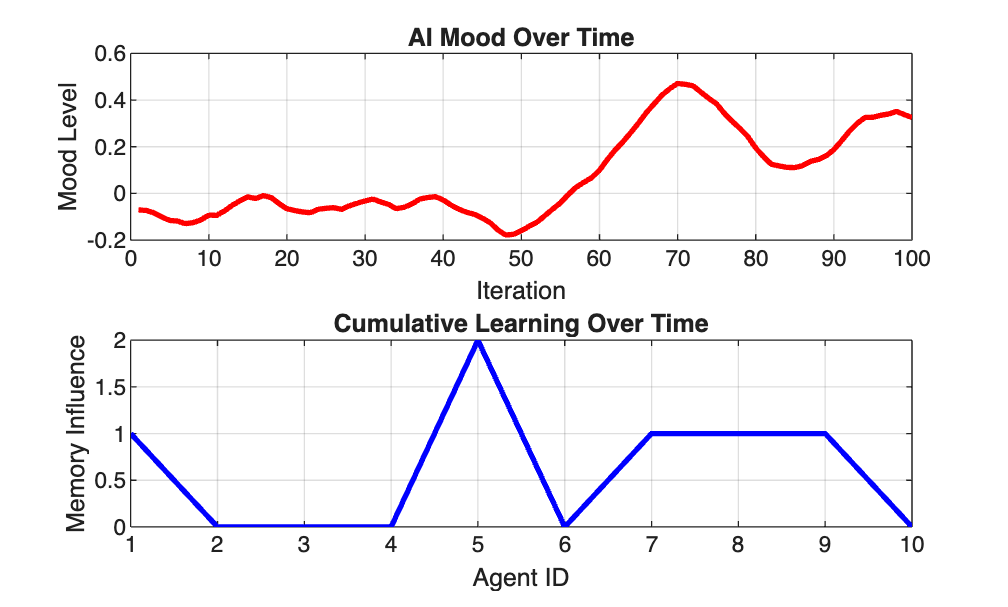


%% Plot Results
figure;
subplot(2,1,1);
plot(1:numIterations, mood(1:numIterations), 'r', 'LineWidth', 2);
title('AI Mood Over Time');
xlabel('Iteration');
ylabel('Mood Level');
grid on;

subplot(2,1,2);
plot(1:size(memory,1), sum(memory(:,1:end),2), 'b', 'LineWidth', 2);
title('Cumulative Learning Over Time');
xlabel('Agent ID');
ylabel('Memory Influence');
grid on;